## Options

set(groot,'defaultAxesTickDir','out')
set(groot,'defaultAxesTickDirMode','manual');
set(groot,'defaultaxesfontname','Arial')
set(groot,'defaultaxesfontsize',12,'defaultaxesfontname','Arial')
set(groot,'defaultFigureWindowStyle','normal');

fig_format = {'fig','png'};         % to avoid saving figures use fig_format = {};

datafile = 'all_data_with_weights.mat';


## Compute psychometric and chronometric curves, and logistic regression weights

% get the data
load ('all_data.mat');

% show the number of subjects in each dataset
groupcounts(sub_data,"dataset")

ans = 5×3 table
    dataset    GroupCount    Percent
    _______    __________    _______

       1           15        18.987 
       2           19        24.051 
       3           17        21.519 
       4           11        13.924 
       5           17        21.519 



% perform logistic regression
[trl_data, sub_data] = analysis_logreg(trl_data, sub_data);

% compute psychometric and chronometric curves with 5 bins
[sub_data] = analysis_psychometric(trl_data, sub_data, fig_format,5);

% now save the data (so that the remaining analyses can be run easily
save(datafile,'sub_data','trl_data');


## Generate Figure 5B

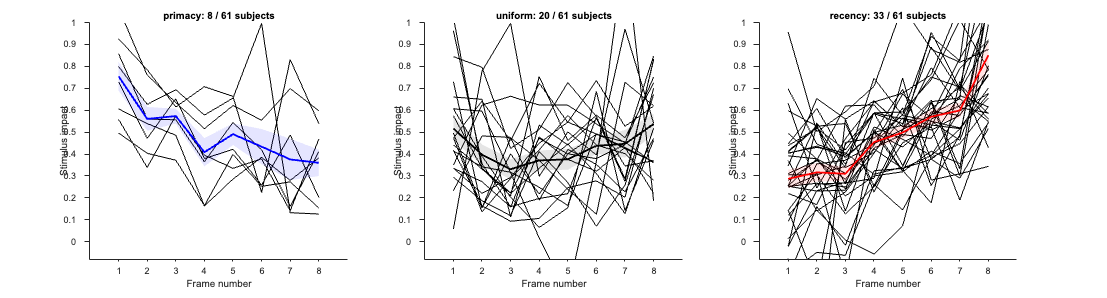

% PK slope => show only for datasets 1,2,3,4
% (dataset 5 is not included here because it is the same subjects from task
% 3 but in the divided attention condition that leads to more recency)
load(datafile,'sub_data');
sub_data = sub_data(sub_data.dataset ~= 5 & (sub_data.included == 'yes' | sub_data.included == 'short_RT'),:);
show_PK_avg(sub_data, fig_format);                          % n = 61

## Generate Figure 6D

Show relationship between the shape of the PK and the average response times (dataset 5 is not included here because it is the same subjects from task 3 but in the divided attention condition that leads to more recency and worse performance). Dataset 4 is also excluded because the subjects make a continuous response, which is quite different from a button press because it is realized through a movement of the computer mouse.

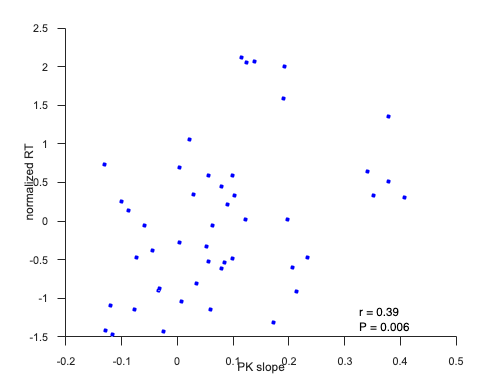

load(datafile,'sub_data');
sub_data = sub_data(ismember(sub_data.dataset,1:3) & sub_data.included == 'yes',:);
show_RT_vs_kernel_shape(sub_data, fig_format);          % n = 47

## Generate Figure S10D

Plot the average psychometric and chronometric functions, averged across all subjects (5 datapoints, as in dataset 1). Show average RTs as a function of stimulus evidence (for correct and incorrect choices).

Note that dataset 5 is not included here because it is the same subjects from task 3 but in the divided attention condition that leads to more recency and worse performance). Dataset 4 is also excluded because the subjects make a continuous response, which is quite different from a button press because you have to move the mouse to some position.

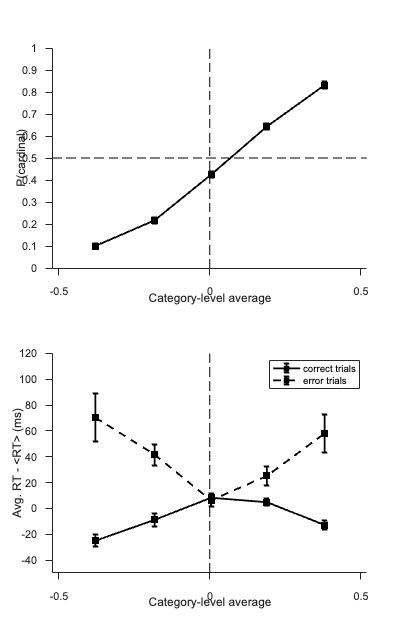

load(datafile,'sub_data');
sub_data = sub_data(ismember(sub_data.dataset,1:3) & sub_data.included == 'yes',:);
show_PM_avg(sub_data, fig_format);          % n = 47 subjects

## Generate Figure S8

Compute the PK for all subjects, and plot - sorted by PK slope. Only show for datasets 1-4.

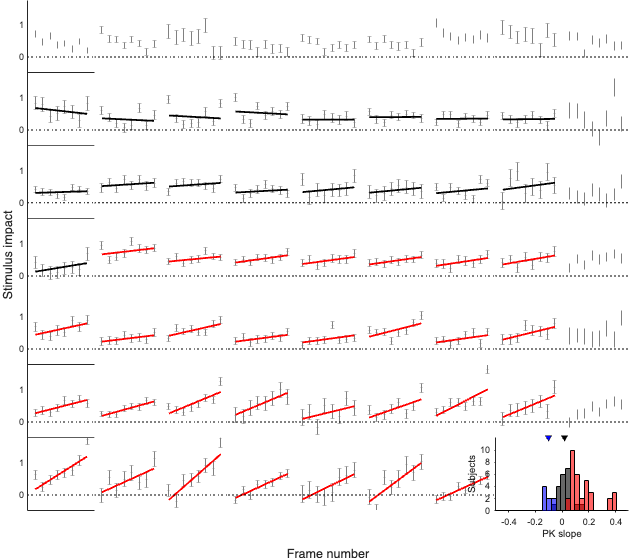

load(datafile,'sub_data');
sub_data = sub_data(sub_data.dataset ~= 5 & (sub_data.included == 'yes' | sub_data.included == 'short_RT'),:);
show_PK_individual(sub_data, fig_format);           % n = 61

## Generate Figure S9B,C

Show PK slope for focused and divided attention (dataset 3 vs. dataset 5)

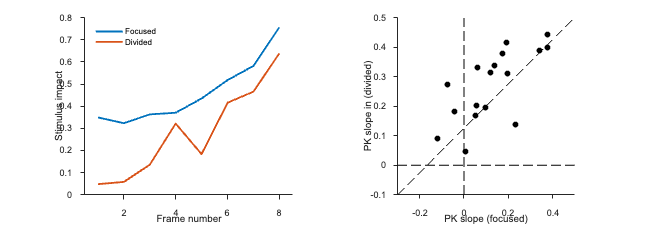

load(datafile,'sub_data');
show_attention(sub_data, fig_format);